%% MICRORHEOLOGY WORKSHOP

clear;  close all; clc;


%% ===================== 1. SETUP =====================
fileName = 'test2.avi';

cd /home/oscar/Escriptori/MOB/MOB_microrheology_tests/


BeadsDiameter = 1;  % µm
pixelSize = 0.25;   % µm/px

minimumTrackLength = 0.5; % s

fprintf('Setup done\n');

Setup done


%% ===================== 2. LOAD VIDEO =====================
V = VideoReader(fileName);
nFrames = floor(V.Duration * V.FrameRate);
l = round(V.Duration*V.FrameRate);
frameRate = V.FrameRate;
StartTime = V.CurrentTime;
FRAMES = zeros(V.Height, V.Width,nFrames, 'uint8');

k = 1;
while hasFrame(V)
    FRAMES(:,:,k) = rgb2gray(readFrame(V));
    k = k + 1;
end

frameHeight = round(V.Height*pixelSize);
frameWidth = round(V.Width*pixelSize);

fprintf('Video loaded\n');

Video loaded


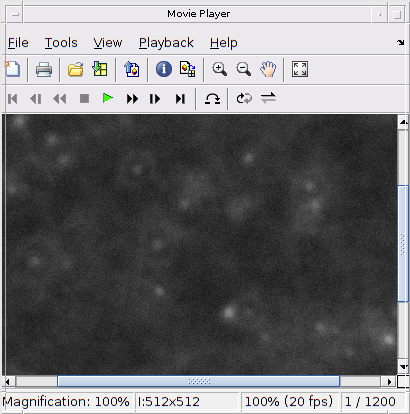

%% ===================== 3. PLAY VIDEO =====================
% check that the video looks good, meaning:
% - that beads are clearly distinguishable over a dark background.
% - that it is not too crowded
% ' that there is no drift
%  If the video is not good,  perhaps try taking one.
%  Remember: rubish in, rubish out.
implay(uint8(rescale(FRAMES,0,255)))

%% ===================== 4. BEADS DETECTION =====================
intensityThreshold = 0.15; % If empty, defaults to Otsu
circularityThreshold = 0.9; % where 1 is a perfect circle, 0 a line
[Centroids, Boundaries, Area, PixelIdxList] =...
    beads_detection(FRAMES, pixelSize, BeadsDiameter, intensityThreshold, circularityThreshold);

fprintf('Detection done\n');

Detection done


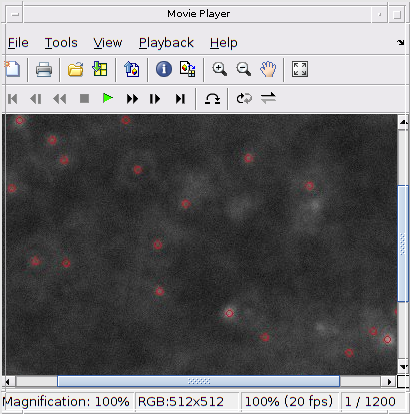

%% ===================== 5. DETECTION CHECK =====================
% Check that beads were detected correctly. Otherwise, redo the previous
% step changing the thresholds

FRAMES = uint8(rescale(FRAMES,0,255));% Normalize once

W = VideoWriter([fileName '_tracks.avi']);
W.FrameRate = frameRate;
W.Quality = 85;

open(W)

nFrames = size(FRAMES,3);
for iFrame = 1:nFrames

    frame = FRAMES(:,:,iFrame);

    % Convert to RGB (needed for colored markers)
    frameRGB = repmat(frame, [1 1 3]);

    % Add bead positions
    if ~isempty(Centroids{iFrame})
        frameRGB = insertMarker(frameRGB, Centroids{iFrame}, ...
            'o', 'Color', 'red', 'Size', 3);
    end

    writeVideo(W, frameRGB);
end

close(W);
implay([fileName '_tracks.avi']);

%% ===================== 6. TRACKING =====================
tracks = beads_tracker(Centroids, Boundaries, PixelIdxList, Area, pixelSize, frameRate, minimumTrackLength);
fprintf('Tracking done\n');

Tracking done


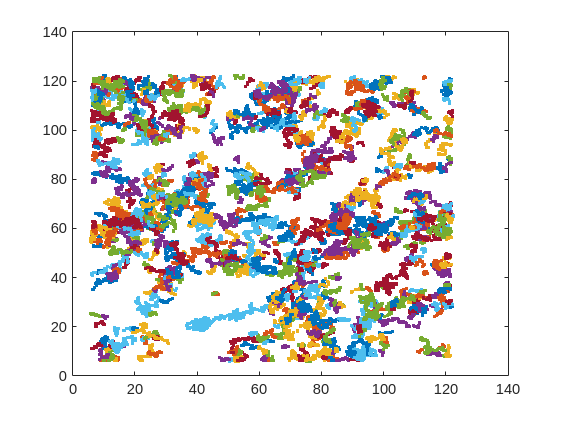

%% ===================== 7. Tracks checking =====================D
% check that there is enough tracks, that there is no clear drift and that
% they are evenly distributed
figure
X = squeeze(tracks(:,3,:));
Y = squeeze(tracks(:,4,:));
h = plot(X,Y,'.');

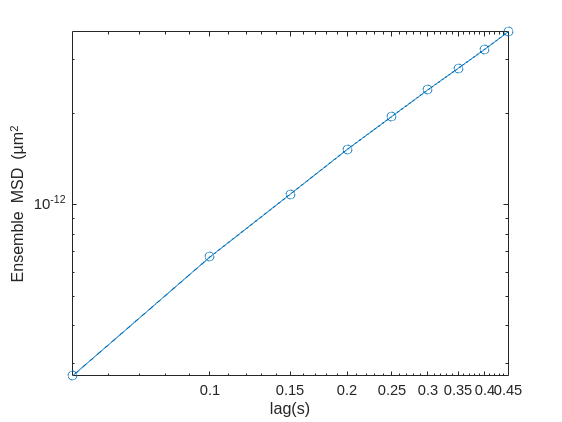

%% ===================== 8. Compute MSDs =====================
% binLength is the length (in microns) of the square pixels in the viscosity map.
% To compute the ensemble MSD for the entire frame, set binLength = frameWidth*pixelSize*1e-6
%
binLength = frameWidth*pixelSize*1e-6;
% binLength = 10e-6;
minimumDuration = 0.5; % minimum duration, in seconds, of a track to be included in the analysis


[lags, MSD, D, N, R, xbins, ybins] = computeMSDs(tracks, pixelSize, frameRate, frameWidth, frameHeight, ...
    binLength, minimumDuration);

figure
loglog(lags,squeeze(nanmean(MSD,[1,2])),'o-')

xlabel('lag(s)')
ylabel('Ensemble MSD (µm^2')



fprintf('MSD calculation done\n');

MSD calculation done


%% ===================== 9. Compute viscosities=====================
% binLength is the length (in microns) of the square pixels in the viscosity map.
% To compute the ensemble MSD for the entire frame, set binLength = frameWidth*pixelSize*1e-6

Temperature = 27;   % °C
Salinity    = 0;   % ppt

K = Temperature+273.15; % temperature in Kelvins
k_b = 1.38e-23; % Boltzmann constant (J/K)
a = BeadsDiameter*1e-6/2;
empiricalViscosity = k_b*K/6/pi./D./a;
theoreticalViscosity = SW_Viscosity(Temperature, 'C', Salinity, 'ppt');
relativeViscosity = empiricalViscosity./theoreticalViscosity;

fprintf(['Dynamic viscosity (measured, [kg/m-s]): ', num2str(nanmedian(empiricalViscosity(:)))])

Dynamic viscosity (measured, [kg/m-s]): 0.00021981

fprintf(['Relative dynamic viscosity (measured): ', num2str(nanmedian(relativeViscosity(:)))])

Relative dynamic viscosity (measured): 0.2583

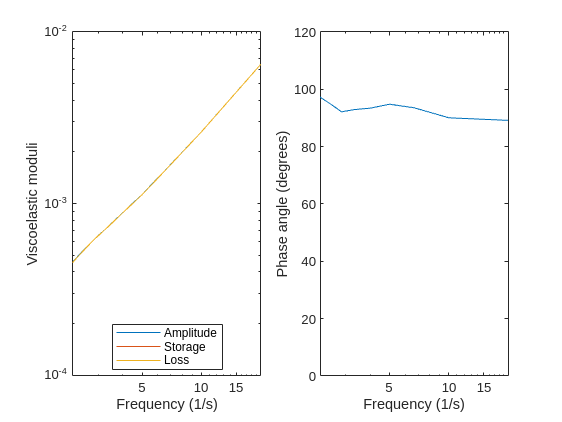

%% ===================== 10. VISCOELASTICITY =====================
amplitude = nan(size(MSD));
phaseAngle =  nan(size(MSD));
storage =  nan(size(MSD));
loss =  nan(size(MSD));
frequency =  nan(size(MSD));
logarithmicSlopes =  nan(size(MSD));


for ii = 1:size(MSD,1)
    for jj=1:size(MSD,2)
        if ~all(isnan(MSD))
            msd = squeeze(MSD(ii,jj,:));
            [amplitude(ii,jj,:), phaseAngle(ii,jj,:), storage(ii,jj,:), loss(ii,jj,:), frequency(ii,jj,:), logarithmicSlopes(ii,jj,:)] =...
                MasonViscoelasticSpectrum(squeeze(MSD(ii,jj,:)), lags, Temperature, 2, BeadsDiameter);
        end
    end
end

figure

% Plot amplitude, storage, and loss moduli vs. frequency
ax(1) = subplot(1, 2, 1);
loglog(squeeze(frequency(1,1,:)),squeeze(nanmean(amplitude,[1,2])))
hold all
loglog(squeeze(frequency(1,1,:)), squeeze(nanmean(storage,[1,2]))) % Plot storage modulus
loglog(squeeze(frequency(1,1,:)), squeeze(nanmean(loss,[1,2])))     % Plot loss modulus
xlabel('Frequency (1/s)')
ylabel('Viscoelastic moduli')
legend('Amplitude', 'Storage', 'Loss','Location','best')

% Plot phase angle vs. frequency
ax(2) = subplot(1, 2, 2);
semilogx(squeeze(frequency(1,1,:)), wrapTo2Pi(squeeze(nanmean(phaseAngle,[1,2]))) * 180 / pi) % Convert phase angle to degrees
xlabel('Frequency (1/s)')
ylabel('Phase angle (degrees)')
ax(2).YLim(1) = 0;
ax(2).YLim(2) = 120;

%% ===================== 11. Viscosity map =====================
%
figure
ax = pcolor(repmat(xbins(1:end-1)',1,length(ybins)-1), repmat(ybins(1:end-1),length(xbins)-1,1),relativeViscosity);

Error using pcolor (line 58)
Color data input must be a matrix.

axis equal
shading flat
cbar = colorbar;
ax.Parent.XTick = [];
ax.Parent.YTick = [];
ax.Parent.XLim = [xbins(1) xbins(end)];
ax.Parent.YLim = [ybins(1) ybins(end)];
ax.Parent.YDir = 'reverse';
try
    cbarLimits(3) = 1;
    cbarLimits(4) = round(prctile(relativeViscosities(:),99)*10/5)*5/10;
    ax(1).CLim = cbarLimits(3:4);
    cbar.Ticks(1) = cbarLimits(3);
    cbar.Ticks(end) = cbarLimits(4);
end
ax.Parent.ColorScale = 'log';
cbar.TickLabels{1} = ['\leq' cbar.TickLabels{1}];
cbar.TickLabels{end} = ['\geq' cbar.TickLabels{end}];
ylabel(cbar,'Relative viscosity')

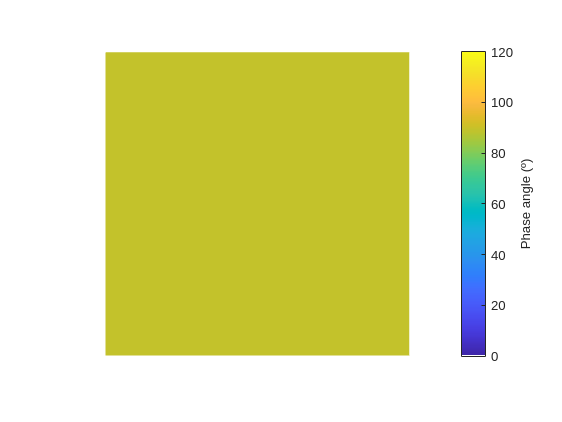

%% ===================== 10. Phase angle map =====================
probingFrequency = 1;

upperPhase = 120;
data = phaseAngle(:,:,probingFrequency)'*180/pi;
data(data<0) = nan;
% data(data>upperPhase) = upperPhase;
% data = rescale(data,0,upperPhase)

hFig = figure(99);
clf
hAx = imagesc(data);
hAx.Parent.CLim = [0 upperPhase];
axis(hFig.Children,'equal')
axis off;
hCb = colorbar;
% cmap = [0,0,0;parula(254);1,0,0]; % Colormap
cmap = [1,1,1;parula(254)]; % Colormap
% cmap = [1,1,1;cmocean('algae',254, 'negative')];
colormap(cmap)
set(hAx, 'AlphaData', ~isnan(data)) % make nans white
ylabel(hCb, 'Phase angle (º)')

%%%%% SUBFUNCTIONS %%%%%%

function [Centroids, Boundaries, Area, PixelIdxList] = beads_detection(FRAMES, pixelSize, BeadsDiameter, intensityThreshold, circularityThreshold)

%% precompute constants
highpass_window = ceil(BeadsDiameter/pixelSize*5);
lowpass_window = floor(0.4 * (BeadsDiameter / pixelSize));
normalize = @(x) x/sum(x);
gaussian_kernel = normalize(...
    exp(-((-ceil(5*lowpass_window):ceil(5*lowpass_window))/(2*lowpass_window)).^2));
boxcar_kernel = normalize(...
    ones(1,length(-round(highpass_window):round(highpass_window))));
minimum_area = round((pi*(BeadsDiameter/pixelSize/4)^2));
maximum_area = round((pi*(BeadsDiameter/pixelSize*4)^2));

%% Normalization
FRAMES = double(FRAMES);
p = prctile(FRAMES(:), [50 99.9]);  % median + high percentile
pmin = p(1);
pmax = p(2);
FRAMES = (255 * min(max((FRAMES - pmin) / (pmax - pmin), 0), 1)); % Rescales between 0 and 255

%% Bandpass filtering
gconv = convn(FRAMES,gaussian_kernel,'same');
gconv = convn(gconv,gaussian_kernel','same');
bconv = convn(FRAMES,boxcar_kernel,'same');
bconv = convn(bconv,boxcar_kernel','same');
FRAMES = gconv - bconv;
FRAMES(FRAMES<0) = 0;
FRAMES = uint8(rescale(FRAMES,0,255));

%% Edge masking
FRAMES(:,1:highpass_window,:) = 0;
FRAMES(1:highpass_window,:,:) = 0;
FRAMES(size(FRAMES,1)-highpass_window:end,:,:) = 0;
FRAMES(:,size(FRAMES,2)-highpass_window:end,:) = 0;

%% Trheshold binarizing
if ~exist('intensityThreshold','var') || isempty(intensityThreshold)
    intensityThreshold = graythresh(FRAMES(:)); %Otsu
end

bw = imbinarize(FRAMES,intensityThreshold);

%% Preallocation of output

nFrames = size(bw,3);
Boundaries   = cell(1, nFrames);
Area         = cell(1, nFrames);
PixelIdxList = cell(1, nFrames);
Centroids    = cell(1, nFrames);



parfor ff = 1:nFrames

    frame = bw(:,:,ff);
    frame = bwareafilt(frame, [minimum_area maximum_area]);

    CC = bwconncomp(frame);
    if CC.NumObjects == 0
        Centroids{ff}    = single([]);
        Area{ff}         = uint16([]);
        PixelIdxList{ff} = {};
        Boundaries{ff}   = {};
        continue
    end

    stats_local = regionprops(CC, ...
        'Area','Centroid','Circularity','PixelIdxList');

    % VECTORIZE
    areas  = [stats_local.Area]';
    circ   = [stats_local.Circularity]';
    cents  = reshape([stats_local.Centroid],2,[])';
    pixels = {stats_local.PixelIdxList}';

    % FILTER
    isCircular = circ >= circularityThreshold;

    if ~any(isCircular)
        Centroids{ff}    = single([]);
        Area{ff}         = uint16([]);
        PixelIdxList{ff} = {};
        Boundaries{ff}   = {};
        continue
    end

    areas  = uint16(areas(isCircular));
    cents  = single(cents(isCircular,:));
    pixels = pixels(isCircular);

    % COMPUTE BOUNDARIES ONLY IF NEEDED
    B = bwboundaries(frame, 'noholes');
    B = B(isCircular);
    B = cellfun(@uint16, B, 'UniformOutput', false);

    Centroids{ff}    = cents;
    Area{ff}         = areas;
    PixelIdxList{ff} = pixels;
    Boundaries{ff}   = B;
end


function tracks = beads_tracker(Centroids, Boundaries, PixelIdx, Area, pixelSize, frameRate, minimumTrackLength)

nFrames = numel(Centroids);

%% ===== TRACKING =====
mm = 0;
dummy = Boundaries;
t{1} = [];

for ff = 1:nFrames % frame
    for pp = 1:length(Boundaries{ff}) % particle
        if isempty(dummy{ff}{pp})
            continue
        end
        mm = mm+1;
        e = pp;
        t{mm} = [ff,pp]; % [frame, particle]
        for kk = ff:nFrames-1 % frame
            %% using for loop
            % only looking at near particles in the next frame
            if isempty(PixelIdx{kk+1})
                break
            end

            distances = sqrt(sum((Centroids{kk+1}-repmat(Centroids{kk}(e,:),size(Centroids{kk+1},1),1)).^2,2));
            near = find(distances<=1/pixelSize*5); % finds particles in the following frame that are near the current particle (i,e, less than 5 microns away)
            E = false(length(near),1);
            for bb = 1:length(near)
                E(bb) = any(intersect(PixelIdx{kk}{e},PixelIdx{kk+1}{near(bb)}));
            end
            e = near(E);
            if isscalar(e)
                t{mm} = [t{mm};kk+1,e]; % first column of each track is the frame, second is the particle
                dummy{kk+1}{e} = []; % to remove particles that cross each
                % and to avoid retracking already tracked particles
            elseif numel(e)>1
                for ll = 1:numel(e)
                    dummy{kk+1}{e(ll)} = []; % to remove particles that cross each
                    % and to avoid retracking already tracked particles
                end
                break
            else
                break
            end
        end
    end
end
t = cellfun(@uint16,t,'UniformOutput', 0);


% ===== FILTER SHORT TRACKS =====
minLen = floor(frameRate * minimumTrackLength);
Cnrows = cellfun('size', t, 1);
t = t(Cnrows >= minLen);

nTracks = numel(t);

% ===== PREALLOCATE =====
tracks = nan(nFrames,5,nTracks,'single'); % allocate full size immediately

warning('off','MATLAB:inpolygon:ModelingWorldLower')

% ===== MAIN LOOP =====
for jj = 1:nTracks

    tj = t{jj};
    L = size(tj,1);

    % assign frame + particle ID
    tracks(1:L,1:2,jj) = tj;

    % ===== VECTORIZE INNER LOOP =====
    frames = tj(:,1);
    ids    = tj(:,2);

    % positions
    XY = cell2mat(arrayfun(@(i) Centroids{frames(i)}(ids(i),:), ...
        1:L, 'UniformOutput', false)') .* pixelSize;

    tracks(1:L,3:4,jj) = XY;

    % area
    A = arrayfun(@(i) Area{frames(i)}(ids(i)), 1:L);
    tracks(1:L,5,jj) = single(A) * pixelSize^2;
end

% ===== TRACK SPLITTING =====
minimum_area = pi()*2*1;

divided = nan(nFrames,5,0,'single');

for jj = 1:size(tracks,3)

    tr = tracks(:,:,jj);

    % detect jumps
    kk = find(abs(diff(tr(:,5))) > minimum_area);

    if isempty(kk), continue; end

    if kk(1) ~= 1
        kk = [1; kk];
    end

    k = find(~isnan(tr(:,5)), 1, 'last');
    if kk(end) ~= k
        kk = [kk; k];
    end

    FF = flip(kk(2:end-1));

    for ii = 1:numel(FF)

        seg = tr(FF(ii):kk(end),:);
        validLen = sum(~isnan(seg(:,3)));

        if validLen >= minLen
            newTrack = nan(nFrames,5,'single');
            newTrack(1:size(seg,1),:) = seg;

            divided(:,:,end+1) = newTrack; %#ok<AGROW>
        end

        tr(FF(ii):kk(end),:) = NaN;
    end

    tracks(:,:,jj) = tr;
end

% ===== MERGE =====
tracks = cat(3, tracks, divided);

% ===== FINAL FILTER =====
valid = squeeze(sum(~isnan(tracks(:,3,:)))) >= minLen;
tracks = tracks(:,:,valid);

end

function [lags, MSD, D, N, R, xbins, ybins] = ...
    computeMSDs(tracks, pixelSize, frameRate, FrameWidth, FrameHeight, ...
    binLength, thresholdLength)

warning('off','stats:statrobustfit:IterationLimit')


X = squeeze(tracks(:,end-2,:))*1e-6;
Y = squeeze(tracks(:,end-1,:))*1e-6;
Y = Y(~all(isnan(X),2),:);
X = X(~all(isnan(X),2),:);

%% ===== TIME VECTOR =====
maxLag = floor(thresholdLength * frameRate);
lags   = (1:maxLag)' / frameRate;


%% ===== MSD (PARTITIONING) =====

% Compute lag matrices
XLAG = lagmatrix(X, 1:maxLag);
YLAG = lagmatrix(Y, 1:maxLag);

XLAG = reshape(XLAG, size(X,1), size(X,2), maxLag);
YLAG = reshape(YLAG, size(Y,1), size(Y,2), maxLag);

SD = (X - XLAG).^2 + (Y - YLAG).^2;

clear XLAG YLAG

% Flatten once (no repeated reshape)
SD = reshape(SD, [], maxLag);
X  = X(:);
Y  = Y(:);

% Remove invalid rows once
valid = ~any(isnan(SD),2);
SD = SD(valid,:);
X  = X(valid);
Y  = Y(valid);

%% ===== GRID =====
xmax = FrameWidth *pixelSize * 1e-6;
ymax = FrameHeight *pixelSize * 1e-6;

xbins = 0:binLength:xmax;
ybins = 0:binLength:ymax;

nx = numel(xbins)-1;
ny = numel(ybins)-1;

D = nan(nx, ny);
N = D;
R = D;
MSD = nan(nx,ny, numel(lags));

%% ===== BINNING + FITTING =====
for xx = 1:nx

    % Pre-filter x once per row
    xmask = (X > xbins(xx)) & (X <= xbins(xx+1));

    for yy = 1:ny

        idx = xmask & (Y > ybins(yy)) & (Y <= ybins(yy+1));

        if ~any(idx), continue, end

        msd_z = mean(SD(idx,:),1);

        N(xx,yy) = nnz(idx);

        % Check full-length validity (unchanged logic)
        if sum(~isnan(msd_z)) == maxLag

            mdl = fitlm(4*[0;lags], [0; msd_z(:)], ...
                'RobustOpts','on','Intercept',false);

            D(xx,yy) = mdl.Coefficients.Estimate;
            R(xx,yy) = mdl.Rsquared.Adjusted;
        end
        MSD(xx,yy,:) = msd_z;
    end

end

end

function YLag = lagmatrix(Y,lags)
%LAGMATRIX Create matrix of lagged time series
%
% Syntax:
%
%   YLag = lagmatrix(Y,lags)
%
% Description:
%
%   Create a matrix of lagged (time-shifted) series. Positive lags
%   correspond to delays; negative lags correspond to leads.
%
% Input Arguments:
%
%   Y - Time series data. Y may be a vector or a matrix. If Y is a vector,
%     it represents a single series. If Y is a numObs-by-numSeries matrix,
%     it represents numObs observations of numSeries series, with
%     observations across any row assumed to occur at the same time. The
%     last observation of any series is assumed to be the most recent.
%
%   lags - Vector of integer delays or leads, of length numLags, applied to
%     each series in Y. The first lag is applied to all series in Y, then
%     the second lag is applied to all series in Y, and so forth. To
%     include an unshifted copy of a series in the output, use a zero lag.
%
% Output Argument:
%
%   YLag - numObs-by-(numSeries*numLags) matrix of lagged versions of the
%     series in Y. Columns of YLag are, in order, all series in Y lagged by
%     the first lag in lags, all series in Y lagged by the second lag in
%     lags, and so forth. Unspecified observations (presample and
%     postsample data) are padded with NaN values.
%
% Example:
%
%       Y = [(1:5)' (-2:2)']     % 2 series
%       lags = [-1 0 1];         % 3 lags
%       YLag = lagmatrix(Y,lags) % 2*3 = 6 lagged series
%
% See also FILTER.

% Copyright 1999-2010 The MathWorks, Inc.   

if nargin ~= 2
    
    error(message('econ:lagmatrix:UnspecifiedInput'))
      
end

% Check for a vector:

if numel(Y) == length(Y)
   Y = Y(:); % Ensure a column vector
end

% Ensure lags is a vector of integers:

if numel(lags) ~= length(lags) % Check for vector
    
   error(message('econ:lagmatrix:NonVectorLags'))
     
end

lags = lags(:); % Ensure a column vector

if any(round(lags)-lags)
    
   error(message('econ:lagmatrix:NonIntegerLags'))
     
end

missingValue = NaN;  % Assign default missing value

% Cycle through the lags vector and shift the input time series. Positive 
% lags are delays, and can be processed by FILTER. Negative lags are leads,
% and series are flipped (reflected in time), run through FILTER, and then
% flipped again. Series with zero lags are simply copied.

numLags = length(lags); % Number of lags to apply to each time series

[numObs,numSeries] = size(Y);

YLag = missingValue(ones(numObs,numSeries*numLags)); % Preallocate

for c = 1:numLags

    L       = lags(c);
    columns = (numSeries*(c-1)+1):c*numSeries; % Columns to fill, this lag

    if L > 0 % Time delays

       YLag((L + 1):end,columns) = Y(1:(end - L), :);

    elseif L < 0 % Time leads

       YLag(1:(end + L),columns) = Y((1 - L):end, :);

    else % No shifts

       YLag(:,columns) = Y;

    end

end
end

function [amplitude, phaseAngle, storage, loss, frequency, logarithmicSlopes] =...
    MasonViscoelasticSpectrum(MSD, lags, Temperature, Dimensionality, BeadsDiameter, fileName,blur)

% MasonViscoelasticSpectrum calculates the viscoelastic spectrum from
% mean square displacement (MSD) data, using Mason (2000) approach.
%
% Inputs:
%   MSD - Mean square displacement data
%   lags - Time lags corresponding to the MSD data
%   Temperature - Temperature in degrees Celsius
%   Dimensionality - Dimensionality of the system (e.g., 2 for 2D, 3
%       for 3D)
%   BeadsDiameter - Diameter of the beads used in the
%       measurement (in micrometers)
%   plotting - Boolean flag to indicate
%       whether to plot results (1 for yes, 0 for no)
%
% Outputs:
%   amplitude - Amplitude of the viscoelastic response
%   phaseAngle - Phase angle of the viscoelastic response
%   storage - Storage modulus (G')
%   loss - Loss modulus (G'')
%   frequency - Frequency corresponding to the time lags
%
%
% Bibliography:
%
%
%
%  Oscar Guadayol, oscar_at_guadayol.cat, June 2025

% %% compute localisation noise. This should be better done by trackin aa fixed bead
% sigma_loc_sq = localization_noise(lags, MSD);
% MSD_corr = MSD+2*sigma_loc_sq;
% MSD_corr(MSD_corr<0) = nan;

%% compute blur term
if ~exist('blur','var') || isempty(blur)
blur = blur_term(lags, MSD, Dimensionality);
end
MSD_corr = MSD+blur;
% MSD_corr = deblur_MSD(lags,MSD,lags(1));
% MSD_corr = deblur_SavinDoyle(lags, MSD, lags(1), 1e-3 * max(MSD));
MSD_corr(MSD_corr<0) = nan;

% Calculate the logarithmic slopes of the MSD with respect to the lags
% logarithmicSlopes = gradient(log(MSD), log(lags)); % Eq 7 in Mason 2000, 3.141 in Furst & Squires 2017
span = 0.1;  % fracció (10% dels punts en cada finestra)
y_loess = smooth(log(lags), log(MSD_corr), span, 'rloess');  % LOESS amb pesos robustos
logarithmicSlopes = gradient(y_loess, log(lags)); % Eq 7 in Mason 2000, 3.141 in Furst & Squires 2017

% % Check for logarithmic slopes outside the range [0, 1]
% % This may indicate issues with the measurement, such as noise or drift
% % See section 3.6.1 in Furst & Squires 2017
if any(logarithmicSlopes < -0.1 | logarithmicSlopes > 1.1)
    % disp('Some logarithmic slopes are outside range. Check for drift or vibrations')
    % this is not always true. If there is a consistent trend in the
    % slopes, then yes. Usually what happens is that there are not enough
    % tracks, particularly at large lags, and the slope becomes unstable
end

% Convert temperature from Celsius to Kelvin
K = Temperature + 273.15; % Temperature in Kelvins
k_b = 1.38e-23; % Boltzmann constant (J/K)

% Calculate the radius of the beads in meters
a = BeadsDiameter * 1e-6 / 2; % Convert diameter from micrometers to meters

% Calculate the amplitude of the viscoelastic response
% Eq 12 in Mason 2000, 3.145 in Furst & Squires 2017
amplitude = (Dimensionality * k_b * K) ./ (3 * pi * a * MSD(:) .* gamma(logarithmicSlopes + 1));

% Calculate the storage modulus (G') and loss modulus (G'')
% Eqs 10 and 11 in Mason 2000, 3.146 and 3.147 in Furst & Squires 2017
storage = amplitude .* cos(pi * logarithmicSlopes / 2);
loss = amplitude .* sin(pi * logarithmicSlopes / 2);

% Calculate the frequency corresponding to the time lags
frequency = 1 ./ lags;

% Calculate the phase angle in radians
% Eq 3.149 in Furst & Squires 2017
phaseAngle = pi / 2 * logarithmicSlopes;

% Plotting results if the plotting flag is set to true
if exist('fileName','var') && ~isempty(fileName)
    hFig = figure(89);
    clf
    % Plot MSD vs. time lags
    ax(1) = subplot(3, 1, 1);
    loglog(lags, MSD)
    xlabel('Time (s)')
    ylabel('MSD (microns^2)')

    % Plot amplitude, storage, and loss moduli vs. frequency
    ax(2) = subplot(3, 1, 2);
    loglog(frequency, amplitude)
    hold all
    loglog(frequency, storage) % Plot storage modulus
    loglog(frequency, loss)     % Plot loss modulus
    xlabel('Frequency (1/s)')
    ylabel('Viscoelastic moduli')
    legend('Amplitude', 'Storage', 'Loss','Location','best')

    % Plot phase angle vs. frequency
    ax(3) = subplot(3, 1, 3);
    semilogx(frequency, wrapTo2Pi(phaseAngle) * 180 / pi) % Convert phase angle to degrees
    xlabel('Frequency (1/s)')
    ylabel('Phase angle (degrees)')
   ax(3).YLim(1) = 0;
   ax(3).YLim(2) = 120;
   

% Set figure size and resolution
set(hFig, 'Units', 'centimeters', 'Position', [30, 5, 11, 20]);  % Width = 11 cm, Height = approx. auto
exportgraphics(hFig, [fileName '_moduli.png'], ...
    'Resolution', 600, ...
    'BackgroundColor', 'white', ...
    'ContentType', 'image');  % 'image' for RGB PNG

end
end

function mu = SW_Viscosity(T,uT,S,uS)
    % SW_Viscosity    Dynamic viscosity of seawater
    %=========================================================================
    % USAGE:  mu = SW_Viscosity(T,uT,S,uS)
    %
    % DESCRIPTION:
    %   Dynamic viscosity of seawater at atmospheric pressure (0.1 MPa) using
    %   Eq. (22) given in [1] which best fit the data of [2], [3] and [4].
    %   The pure water viscosity equation is a best fit to the data of [5].
    %   Values at temperature higher than the normal boiling temperature
    %   are calculated at the saturation pressure.
    %
    % INPUT:
    %   T  = temperature
    %   uT = temperature unit
    %        'C'  : [degree Celsius] (ITS-90)
    %        'K'  : [Kelvin]
    %        'F'  : [degree Fahrenheit]
    %        'R'  : [Rankine]
    %   S  = salinity
    %   uS = salinity unit
    %        'ppt': [g/kg]  (reference-composition salinity)
    %        'ppm': [mg/kg] (in parts per million)
    %        'w'  : [kg/kg] (mass fraction)
    %        '%'  : [kg/kg] (in parts per hundred)
    %
    %   Note: T and S must have the same dimensions
    %
    % OUTPUT:
    %   mu = dynamic viscosity [kg/m-s]
    %
    %   Note: mu will have the same dimensions as T and S
    %
    % VALIDITY: 0 < T < 180 C and 0 < S < 150 g/kg;
    %
    % ACCURACY: 1.5%
    %
    % REVISION HISTORY:
    %   2009-12-18: Mostafa H. Sharqawy (mhamed@mit.edu), MIT
    %               - Initial version
    %   2012-06-06: Karan H. Mistry (mistry@mit.edu), MIT
    %               - Allow T,S input in various units
    %               - Allow T,S to be matrices of any size
    %
    % DISCLAIMER:
    %   This software is provided "as is" without warranty of any kind.
    %   See the file sw_copy.m for conditions of use and licence.
    %
    % REFERENCES:
    %   [1] M. H. Sharqawy, J. H. Lienhard V, and S. M. Zubair, Desalination
    %       and Water Treatment, 16, 354-380, 2010. (http://web.mit.edu/seawater/)
    %   [2] B. M. Fabuss, A. Korosi, and D. F. Othmer, J., Chem. Eng. Data 14(2), 192, 1969.
    %   [3] J. D. Isdale, C. M. Spence, and J. S. Tudhope, Desalination, 10(4), 319 - 328, 1972
    %   [4] F. J. Millero, The Sea, Vol. 5, 3 � 80, John Wiley, New York, 1974
    %   [5] IAPWS release on the viscosity of ordinary water substance 2008
    %=========================================================================

    %% CHECK INPUT ARGUMENTS

    % CHECK THAT S&T HAVE SAME SHAPE
    if ~isequal(size(S),size(T))
        error('check_stp: S & T must have same dimensions');
    end

    % CONVERT TEMPERATURE INPUT TO °C
    switch lower(uT)
        case 'c'
        case 'k'
            T = T - 273.15;
        case 'f'
            T = 5/9*(T-32);
        case 'r'
            T = 5/9*(T-491.67);
        otherwise
            error('Not a recognized temperature unit. Please use ''C'', ''K'', ''F'', or ''R''');
    end

    % CONVERT SALINITY TO PPT
    switch lower(uS)
        case 'ppt'
        case 'ppm'
            S = S/1000;
        case 'w'
            S = S*1000;
        case '%'
            S = S*10;
        otherwise
            error('Not a recognized salinity unit. Please use ''ppt'', ''ppm'', ''w'', or ''%''');
    end

    % CHECK THAT S & T ARE WITHIN THE FUNCTION RANGE
    if ~isequal((T<0)+(T>180),zeros(size(T)))
        warning('Temperature is out of range for Viscosity function 0<T<180 C');
    end

    if ~isequal((S<0)+(S>150),zeros(size(S)))
        warning('Salinity is out of range for Viscosity function 0<S<150 g/kg');
    end

    %% BEGIN

    S = S/1000;

    a = [
        1.5700386464E-01
        6.4992620050E+01
       -9.1296496657E+01
        4.2844324477E-05
        1.5409136040E+00
        1.9981117208E-02
       -9.5203865864E-05
        7.9739318223E+00
       -7.5614568881E-02
        4.7237011074E-04
    ];

    mu_w = a(4) + 1./(a(1)*(T+a(2)).^2+a(3));


    A  = a(5) + a(6) * T + a(7) * T.^2;
    B  = a(8) + a(9) * T + a(10)* T.^2;
    mu = mu_w.*(1 + A.*S + B.*S.^2);

end
end